## PSO controlled PID controller for AVR system

## AVR Transfer Function

num = [0.1, 10];
den = [0.0004, 0.0454, 0.555, 1.52, 11];

sys = tf(num, den);

### Step response

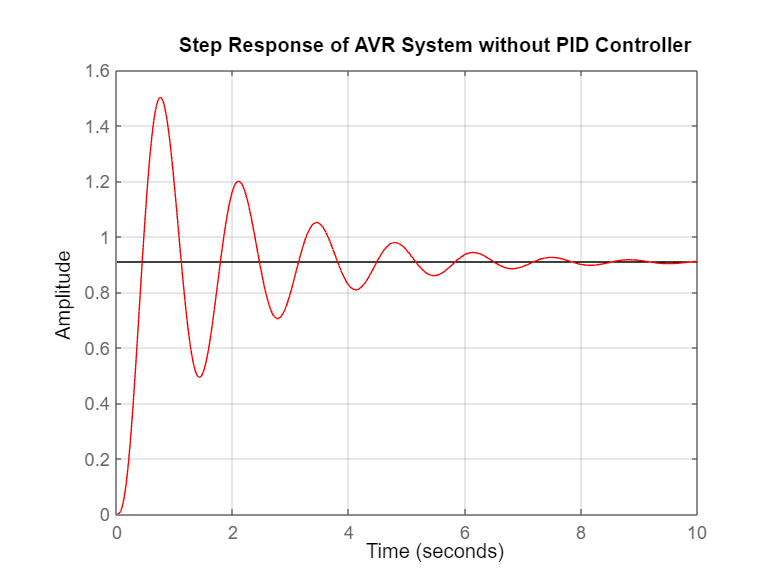

step(sys , 'r');
grid on;
title('Step Response of AVR System without PID Controller');

### Parameters

[y, t] = step(sys);

info = stepinfo(y, t);

Ess = abs(1 - y(end))                           % Steady-state error

Ess = 0.0894

Mp = (max(y)- y(end)) / y(end)                  % Maximum overshoot

Mp = 0.6502

Ts = info.SettlingTime                          % Settling time

Ts = 6.9878

Tr = info.RiseTime                              % Rise time

Tr = 0.2613

## AVR with a PID Controller


num_f = 10;
den_f = [0.04, 0.54, 1.5, 1];
AVR_ForwardPath = tf(num_f, den_f);

num_b = 1;
den_b = [0.01, 1];
AVR_BackwardPath = tf(num_b, den_b);

% PID controller parameters
Kp = 0.6570; % Proportional gain
Ki = 0.5389; % Integral gain
Kd = 0.2458; % Derivative gain

pid_controller = pid(Kp, Ki, Kd);

sys_with_pid = feedback(pid_controller * AVR_ForwardPath, AVR_BackwardPath);


### Step Response

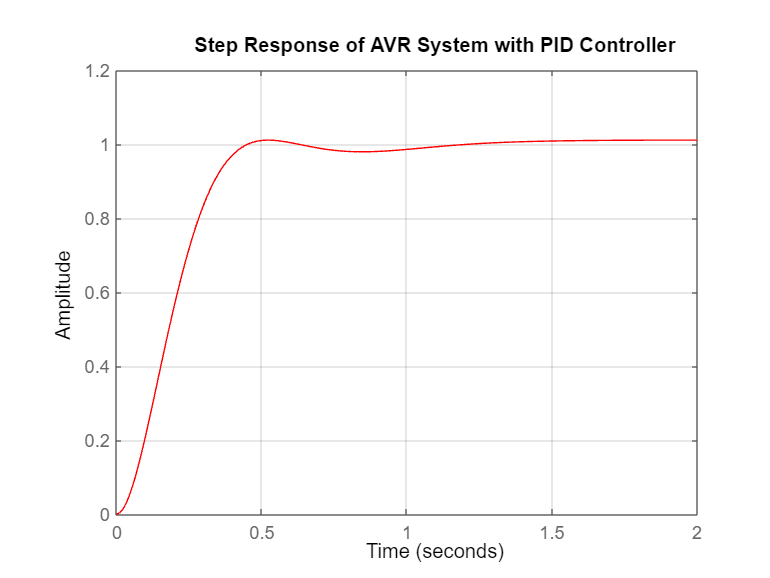

t = 0:0.01:2; 
step(sys_with_pid, t, 'r');
grid on;
title('Step Response of AVR System with PID Controller');

### Parameters

[y, t] = step(sys_with_pid);

info_PID = stepinfo(y, t);

% Extract relevant performance metrics
Ess1 = abs(1 - y(end)) % Steady-state error

Ess1 = 3.5153e-04

Mp1 = (max(y)- y(end)) / y(end) % Maximum overshoot

Mp1 = 0.0112

Ts1 = info.SettlingTime % Settling time

Ts1 = 6.9878

Tr1 = info.RiseTime % Rise time

Tr1 = 0.2613

## PSO

### Initialization

% PSO constants
c = 2;                        % Acceleration Constant
w_max = 0.9;                  % Max Inertial weight
w_min = 0.4;                  % Min Inertial weight
particles = 50;               % No. of Particles
iteration = 50;               % No. of Iterations
Var = 3;                      % No. of Variables
max_stagnation = 5;           % Stagnation count
stagnation_count = 0;

% Range of Controller Parameters
a = [0, 0, 0];
b = [1.5, 1, 1];

% Optimization steps
c_cf = 0;
beta = 1;

% Preallocate space for matrices v, x, and xp
v = zeros(particles, Var);
x = zeros(particles, Var);
xp = zeros(particles, Var);
best_cf_ac = zeros(iteration);

% Initialization
for m=1:particles
    for n=1:Var
        v(m,n)=0;
        x(m,n)=a(n)+rand*(b(n)-a(n));
        xp(m,n)=x(m,n);
    end

    % Model parameters
    kp = x(m,1);
    ki = x(m,2);
    kd = x(m,3);

    % f (Objective Function)
    f(m) = PerformanceCriterion(kp, ki, kd, beta);
end

[Best_performance,location] = min(f);
fg = Best_performance;
xg(1) = x(location,1);
xg(2) = x(location,2);
xg(3) = x(location,3);

### PSO Algorithmn

for i=1:iteration
    w = w_max - ((w_max-w_min)/iteration)*i;
    for m=1:particles
        for n=1:Var
           v(m,n)=(w*v(m,n))+(c*rand*(xp(m,n)-x(m,n)))+(c*rand*(xg(n)-x(m,n)));
           x(m,n)=x(m,n)+v(m,n);
        end
        
        % Checking bound
        for n=1:Var
            if x(m,n) < a(n)
                x(m,n) = a(n);
            end
            if x(m,n) > b(n)
               x(m,n) = b(n);
            end
        end

        % Model parameters
        kp=x(m,1);
        ki=x(m,2);
        kd=x(m,3);
        
        % f (Objective Function)
        fp(m) = PerformanceCriterion(kp, ki, kd, beta);
        
        % compare Local
        if fp(m)<f(m)
            f(m)=fp(m);
            xp(m,1)=x(m,1);
            xp(m,2)=x(m,2);
            xp(m,3)=x(m,3);
        end
    
    end 
   
    if fg == best_cf_ac(c_cf+1)
        stagnation_count = stagnation_count + 1;
    else
        stagnation_count = 0; 
    end
    
    if stagnation_count >= max_stagnation
        disp('Optimization terminated due to stagnation.');
        break; 
    end

     [B_fg,location]=min(f);
     
    %  compare global
    if B_fg<fg
        fg=B_fg;
        xg(1)=xp(location,1);
        xg(2)=xp(location,2);
        xg(3)=xp(location,3);
    end
    c_cf=c_cf+1;
    best_cf_ac(c_cf)=fg;

end


Min_f=fg;
kp = xg(1);
ki = xg(2);
kd = xg(3);

disp("PSO Completed (Yaaaay)");

PSO Completed (Yaaaay)


disp(["Kp : ", num2str(kp)]);

    "Kp : "    "0.65995"



disp(["Ki : ", num2str(ki)]);

    "Ki : "    "0.53109"



disp(["Kd : ", num2str(kd)]);

    "Kd : "    "0.24419"



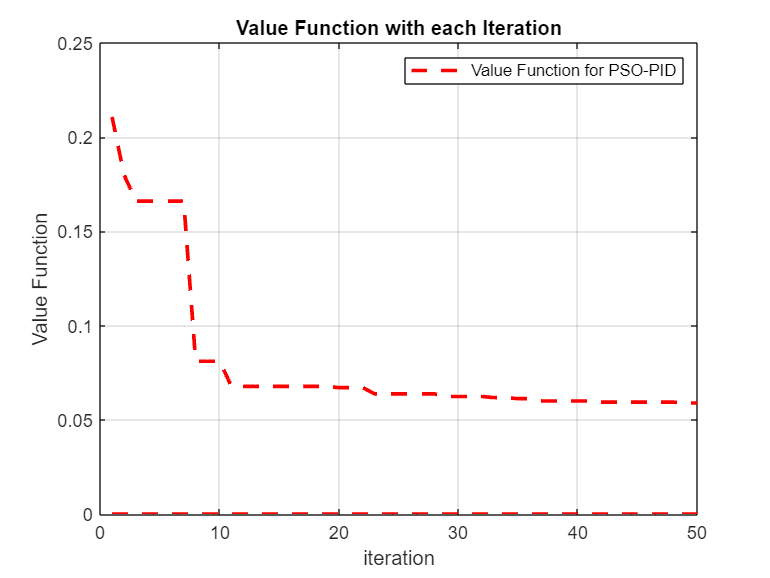


Gc=pid(kp,ki,kd);
Gcf = feedback(Gc*AVR_ForwardPath,AVR_BackwardPath);
y=step(Gcf);

t_cf=1:c_cf;

figure;
plot(t_cf,best_cf_ac,'r--','LineWidth',2),xlabel('iteration'),ylabel('Value Function');
grid on;
legend('Value Function for PSO-PID');
title('Value Function with each Iteration');


pid_controller = pid(kp, ki, kd);
sys_with_pid = feedback(pid_controller * AVR_ForwardPath, AVR_BackwardPath);

W_PID = PerformanceCriterion(kp, ki, kd, 1);
disp("Performance criterion of PSO PID Controller : " + num2str(W_PID));

Performance criterion of PSO PID Controller : 0.058966


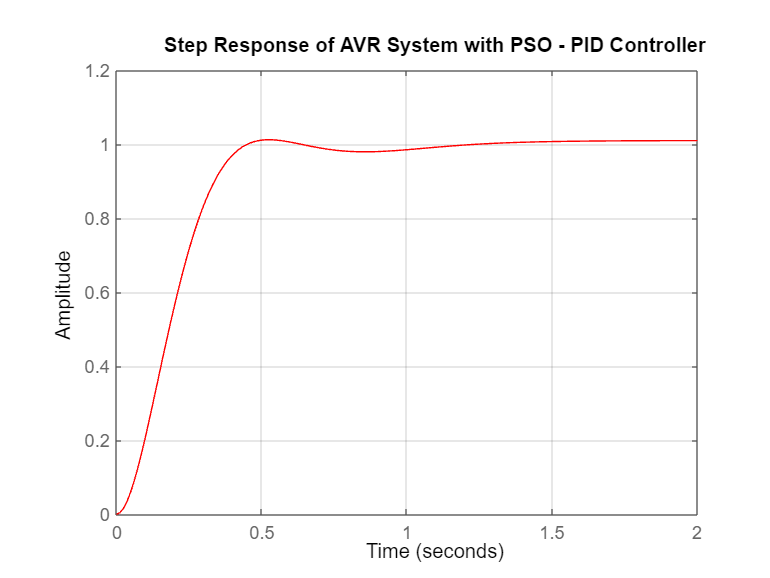


t = 0:0.01:2;
step(sys_with_pid, t, 'r');
grid on;
title('Step Response of AVR System with PSO - PID Controller');

## Performance Criterion : W(k)

function W = PerformanceCriterion(Kp, Ki, Kd, beta)
    num_f = 10;
    den_f = [0.04, 0.54, 1.5, 1];
    AVR_ForwardPath = tf(num_f, den_f);
    
    num_b = 1;
    den_b = [0.01, 1];
    AVR_BackwardPath = tf(num_b, den_b);

    pid_controller = pid(Kp, Ki, Kd);

    sys_with_pid = feedback(pid_controller * AVR_ForwardPath, AVR_BackwardPath);
    
    [y, t] = step(sys_with_pid);
    info = stepinfo(y, t);

    Ess = abs(1 - y(end));                  % Steady-state error
    Mp = (max(y)- y(end)) / y(end);         % Maximum overshoot
    Ts = info.SettlingTime;                 % Settling time
    Tr = info.RiseTime;                     % Rise time

    W = (1-exp(-beta))*(Mp + Ess) + (exp(-beta))*(Ts - Tr);
end
